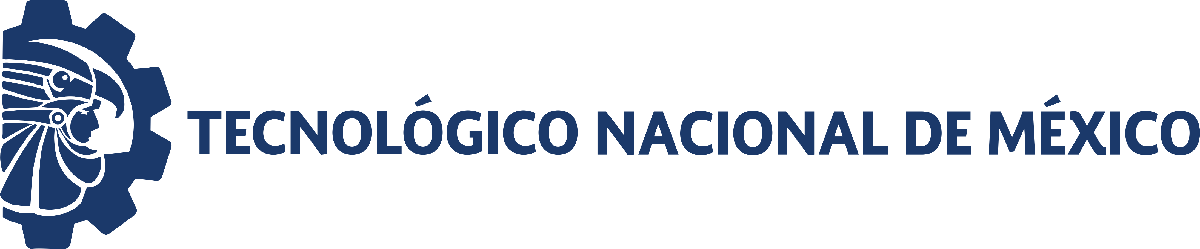                                 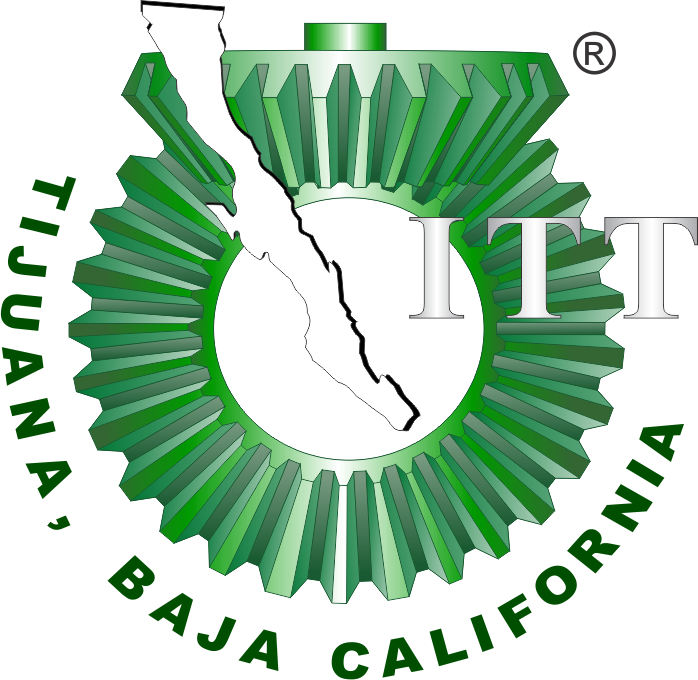

# Proyecto Final: Control de monóxido de carbono en sangre

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre y número de control de los alumnos: 

Escobedo Tellez Yadhira Lisset 20210779

Gonzalez Morales Fabian 18211551

Hernandez Peraza Paola Giselle 19210608

Zabala Silva Rosa Helena 18211599

Correos institucionales:

yadhira.escobedo201@tectijuana.edu.mx

fabian.gonzalez193@tectijuana.edu.mx

paola.hernandez19@tectijuana.edu.mx

rosa.zavala201@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaPF';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Parámetros del controlador y rendimiento

## Sistema de control de monóxido de carbono

set_param('SistemaPF/Pao(t)','Amplitude','1');
set_param('SistemaPF/Pao(t)','Frequency','pi/2');
set_param('SistemaPF/PID Controller','P','10.7123');
set_param('SistemaPF/PID Controller','I','13.7603');
set_param('SistemaPF/PID Controller','D','1.4435');
Signal = 'Sistema de control de monóxido de carbono';
N = sim(file,parameters);

Found algebraic loop that contains: 
SistemaPF/PA(t): Caso/1//R1
SistemaPF/PA(t): Caso/Derivative
SistemaPF/PA(t): Caso/L
SistemaPF/PA(t): Caso/Add (algebraic variable)
Found algebraic loop that contains: 
SistemaPF/PA(t): Control/1//R1
SistemaPF/PA(t): Control/Derivative
SistemaPF/PA(t): Control/1//L


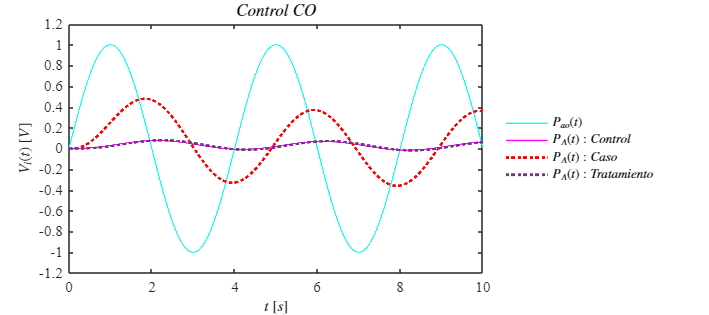

plotsignals(N.t,N.Pao,N.PAx,N.PAy,N.PAz,Signal)

## Función Respuesta a las señales

function plotsignals(t, Pao, PAx, PAy, PAz, Signal)
    set(figure(), 'Color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [1, 1, 18, 8])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)
    hold on; grid off; box on

    plot(t, Pao, 'LineWidth', 1, 'Color', 'c'); 
    plot(t, PAx, 'LineWidth', 1, 'Color', 'm'); 
    plot(t, PAy, ':', 'LineWidth', 2, 'Color', 'r'); 
    plot(t, PAz, ':', 'LineWidth', 2, 'Color', [0.4940 0.1840 0.5560]); 
    hold off; 

    L = legend('$P_{ao}(t)$', '$P_A(t):Control$', '$P_A(t):Caso$', '$P_A(t):Tratamiento$');
    set(L, 'Interpreter', 'Latex', 'FontSize', 9, 'Location', 'EastOutside', 'Box', 'Off')

    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11)
    ylabel('$V_i(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 11)

    if Signal == "Sistema de control de monóxido de carbono"
        title('$Control$ $CO$', 'Interpreter', 'Latex')
        xlim([0, 10]); xticks(0:2:10) 
        ylim([-1.2, 1.2]); yticks(-1.2:0.2:1.2)

    end 
    exportgraphics(gcf, [Signal, '.pdf'], 'ContentType', 'vector')
end
